## 1


A1 = [1 4 2;
     2 4 100;
     7 9 7;
     3 pi 42];

B1 = log(A1);

a1_result = B1(2,:)

a1_result =     0.6931    1.3863    4.6052



b1_result = sum(B1(2,:))

b1_result = 6.6846


c1_result = B1(:,2) .* A1(:,1)

c1_result =     1.3863
    2.7726
   15.3806
    3.4342



d1_result = max(c1_result)

d1_result = 15.3806


e1_vector = A1(1,:) ./ B1(1:3,3)'

e1_vector =     1.4427    0.8686    1.0278


e1_result = sum(e1_vector)

e1_result = 3.3391

## 2


v0 = 50;
A2_deg = 50;
g2 = 9.81;

A2_rad = A2_deg * pi / 180;

% (a)
thit = 2 * v0 * sin(A2_rad) / g2

thit = 7.8088

ymax = (v0^2 * sin(A2_rad)^2) / (2*g2)

ymax = 74.7737

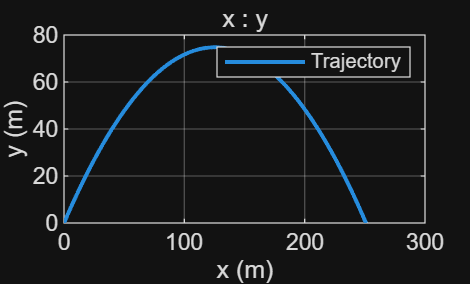


% (b)
t2 = linspace(0, thit, 500);

x2 = (v0*cos(A2_rad)) .* t2;
y2 = (v0*sin(A2_rad)) .* t2 - 0.5*g2*t2.^2;

figure
plot(x2, y2, 'LineWidth', 1.5)
grid on
xlabel('x (m)')
ylabel('y (m)')
title('x : y')
legend('Trajectory')

## 3

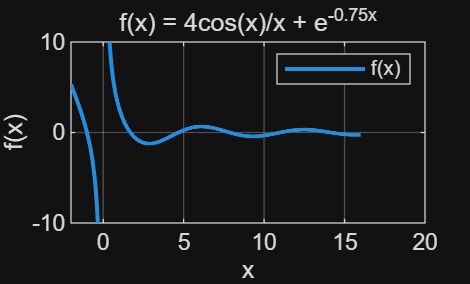


x3 = linspace(-2, 16, 1000);
x3(abs(x3) < 1e-10) = NaN;

f3 = (4*cos(x3))./x3 + exp(-0.75*x3);

figure
plot(x3, f3, 'LineWidth', 1.5)
grid on
xlabel('x')
ylabel('f(x)')
title('f(x) = 4cos(x)/x + e^{-0.75x}')
legend('f(x)')
ylim([-10 10])

## 4


% (a)
C = [5 4 6;
     3 2 4;
     6 5 3;
     3 5 4;
     2 4 3]

C =      5     4     6
     3     2     4
     6     5     3
     3     5     4
     2     4     3


% (b)
monthly_qty = sum(C, 1)

monthly_qty =     19    20    20


% (c)
material_qty = sum(C, 2)

material_qty =     15
     9
    14
    12
     9


% (d)
total_qty = sum(C, 'all')

total_qty = 59

%% 5번
% (a)
a5 = [5 0 -3 7 10];
b5 = [4 -7 9 2];

product_poly = conv(a5, b5)

product_poly =     20   -35    33    59   -36   -13   104    20



% (b)
c5 = [5 -7 2 8];
d5 = [6 3 -2];

[quotient, remainder] = deconv(c5, d5)

quotient =     0.8333   -1.5833


remainder =          0         0    8.4167    4.8333



% (c)
x = 5;
e5 = 36*x^3 - 8*x^2 + 2;
f5 = 36*x^3 - 5*x^2 + 4*x - 3;

value_at_5 = e5 / f5

value_at_5 = 0.9795

## 7

% (a)
bridge(1).location = 'Smith St.';
bridge(1).maxLoad = 80;
bridge(1).yearBuilt = 1928;
bridge(1).serviceLife = 2025;

bridge(2).location = 'Hope Ave.';
bridge(2).maxLoad = 90;
bridge(2).yearBuilt = 1950;
bridge(2).serviceLife = 2027;

bridge(3).location = 'Clark St.';
bridge(3).maxLoad = 85;
bridge(3).yearBuilt = 1933;
bridge(3).serviceLife = 2024;

bridge(4).location = 'North Rd.';
bridge(4).maxLoad = 100;
bridge(4).yearBuilt = 1960;
bridge(4).serviceLife = 2023;


bridge

bridge = 다음 필드를 포함한 1×4 struct 배열:
    location
    maxLoad
    yearBuilt
    serviceLife



% (b)
bridge(3).serviceLife = 2026;

% (c)
bridge(5).location = 'Shore Rd.';
bridge(5).maxLoad = 85;
bridge(5).yearBuilt = 1997;
bridge(5).serviceLife = 2022;

bridge

bridge = 다음 필드를 포함한 1×5 struct 배열:
    location
    maxLoad
    yearBuilt
    serviceLife
